# **Expectation–Maximization Algorithm**

clc; clear; close all
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin');

## Generate Simulation data points

mu = [1,4,0;6,6,4;0,8,4;4,7,9]';
sigma = [3,2,2;1,1.5,4;2,1.5,5;6,8,15];
rot = [20,30,10;50,10,20;50,90,20;10,80,20]/180*pi;
n = [500,300,400,450];

k = 3; % define ellips, 3 sigma, 99.7% of the data within the ellip
n_pt = 50; 

O = cell(1,length(n));
ellips_ref = cell(1,length(n));
for i = 1:length(n)
    s = rotcov(diag(sigma(i,:)),rot(i,:));
    O{i} = randn1(s,n(i),mu(:,i));
    ellips_ref{i} = cov2ellip(s,k,mu(:,i),n_pt);
end

### Plot Original Data

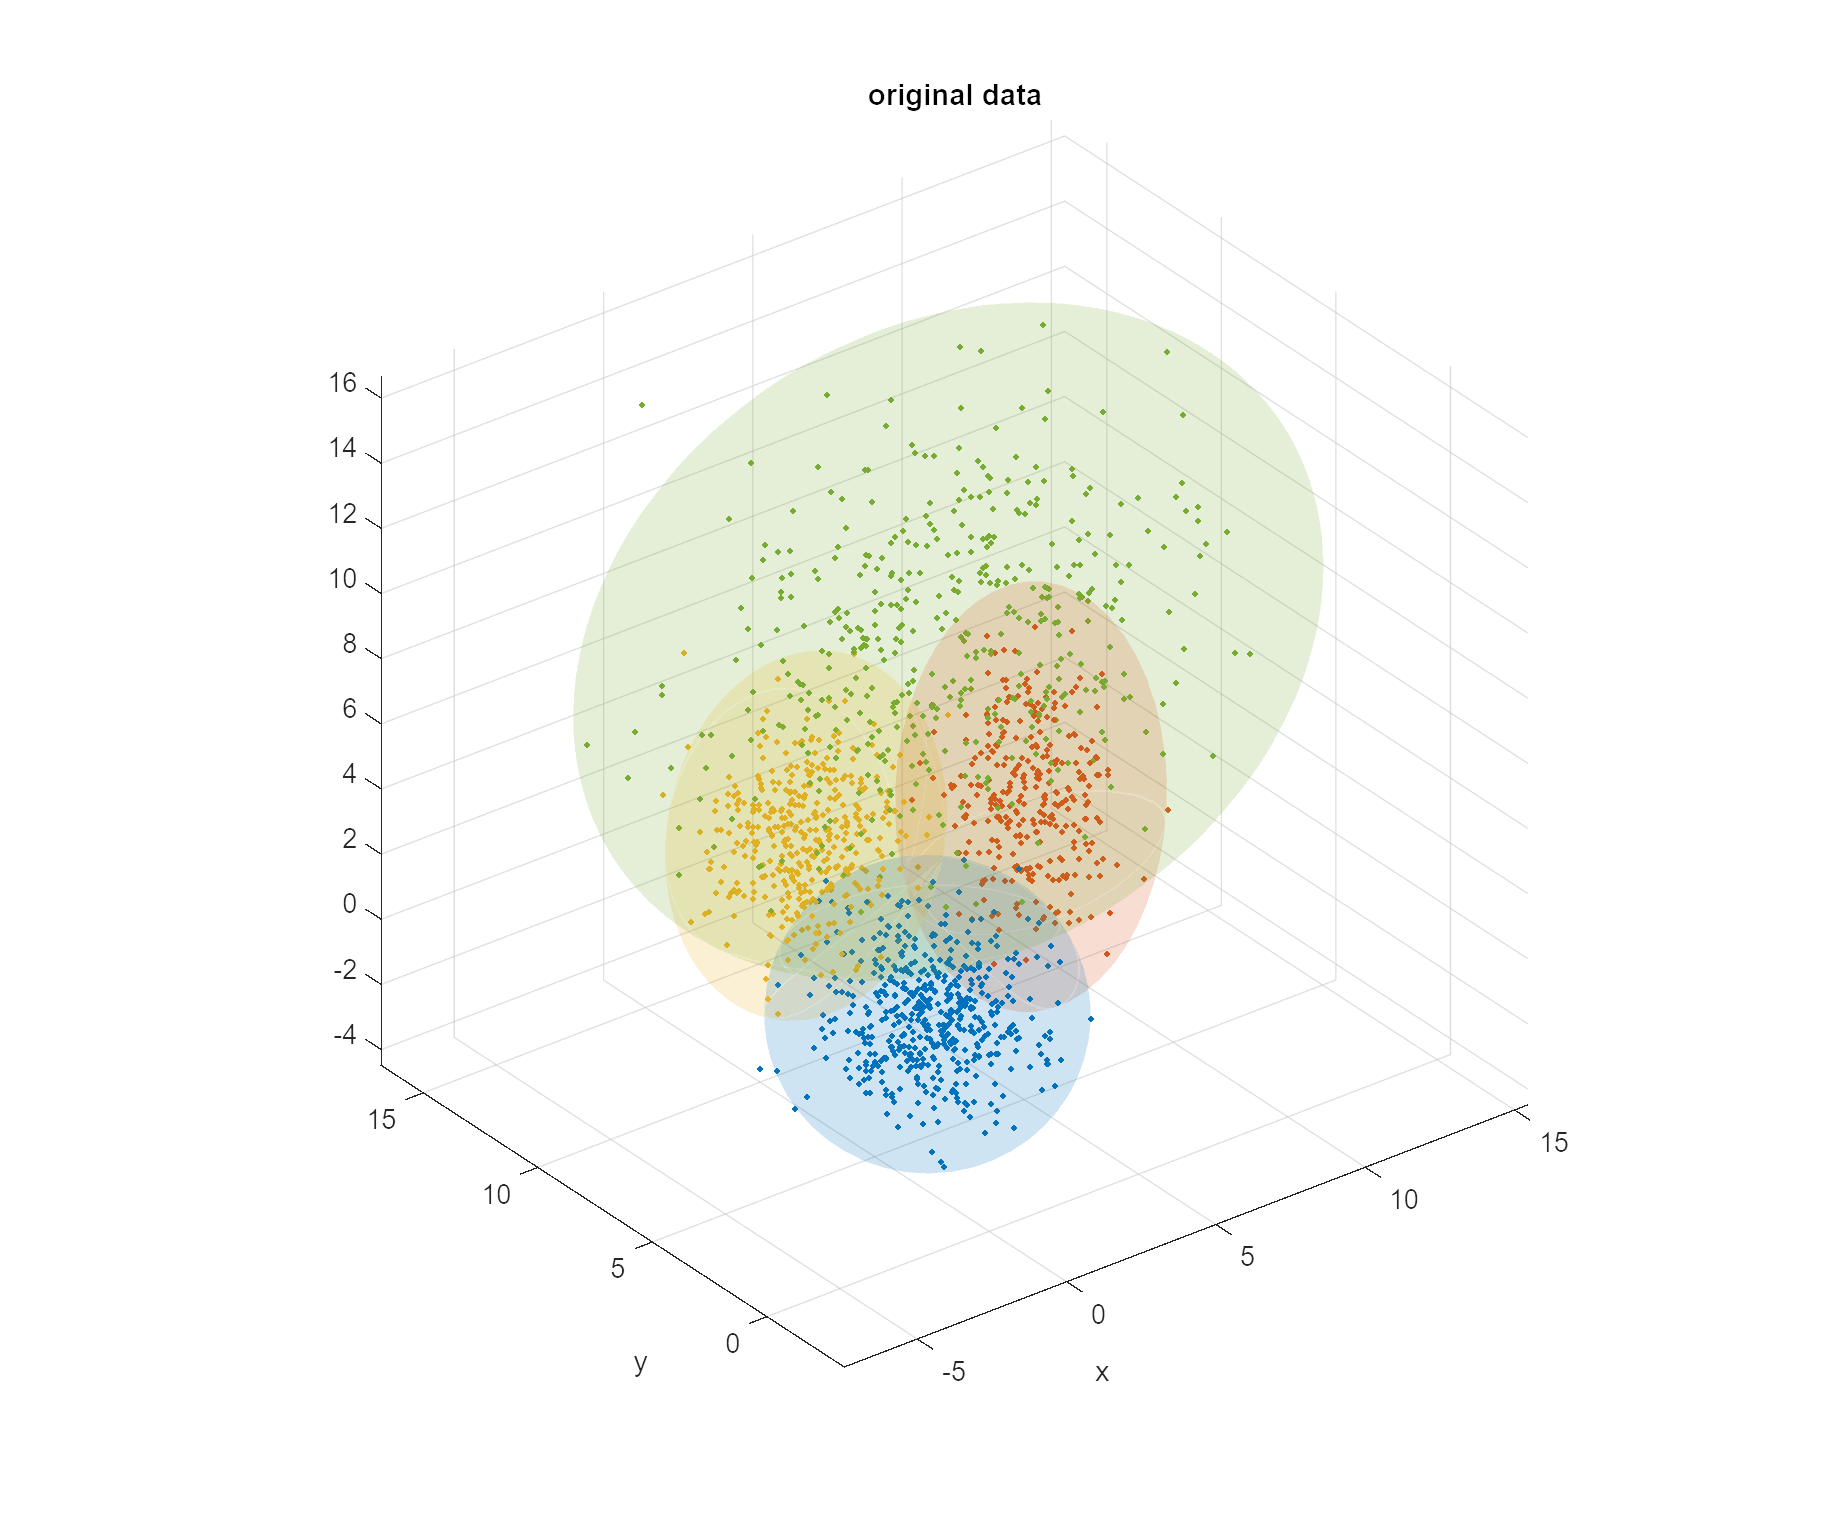

% color for ploting
cl = [0 0.4470 0.7410;
    0.8500 0.3250 0.0980;
    0.9290 0.6940 0.1250;
    0.4660 0.6740 0.1880;
    0.4940 0.1840 0.5560;
    0.3010 0.7450 0.9330;
    0.6350 0.0780 0.1840;
    0,0,1];

f = figure;
for i = 1:length(n)
    plot3(O{i}(1,:),O{i}(2,:),O{i}(3,:),'.','Color',cl(i,:)); hold on
    surf(ellips_ref{i}(:,:,1),ellips_ref{i}(:,:,2),ellips_ref{i}(:,:,3),...
        'EdgeColor','none','FaceColor',cl(i,:),'FaceAlpha',0.1)
end
xlabel('x'); ylabel('y')
grid on; axis equal
title('original data')
set(f,'Units','normalized','Position',[0,0,0.6,0.8])

### Prepare Testing Data

O = cell2mat(O); % mix 3 sets
clearvars -except O ellips_ref cl

### k-mean to get Initial Guess

n_set = 4;
[idx,C,S,iters] = kmeann(O,n_set,100,10,'Seed','++');

### Plot k-mean Results

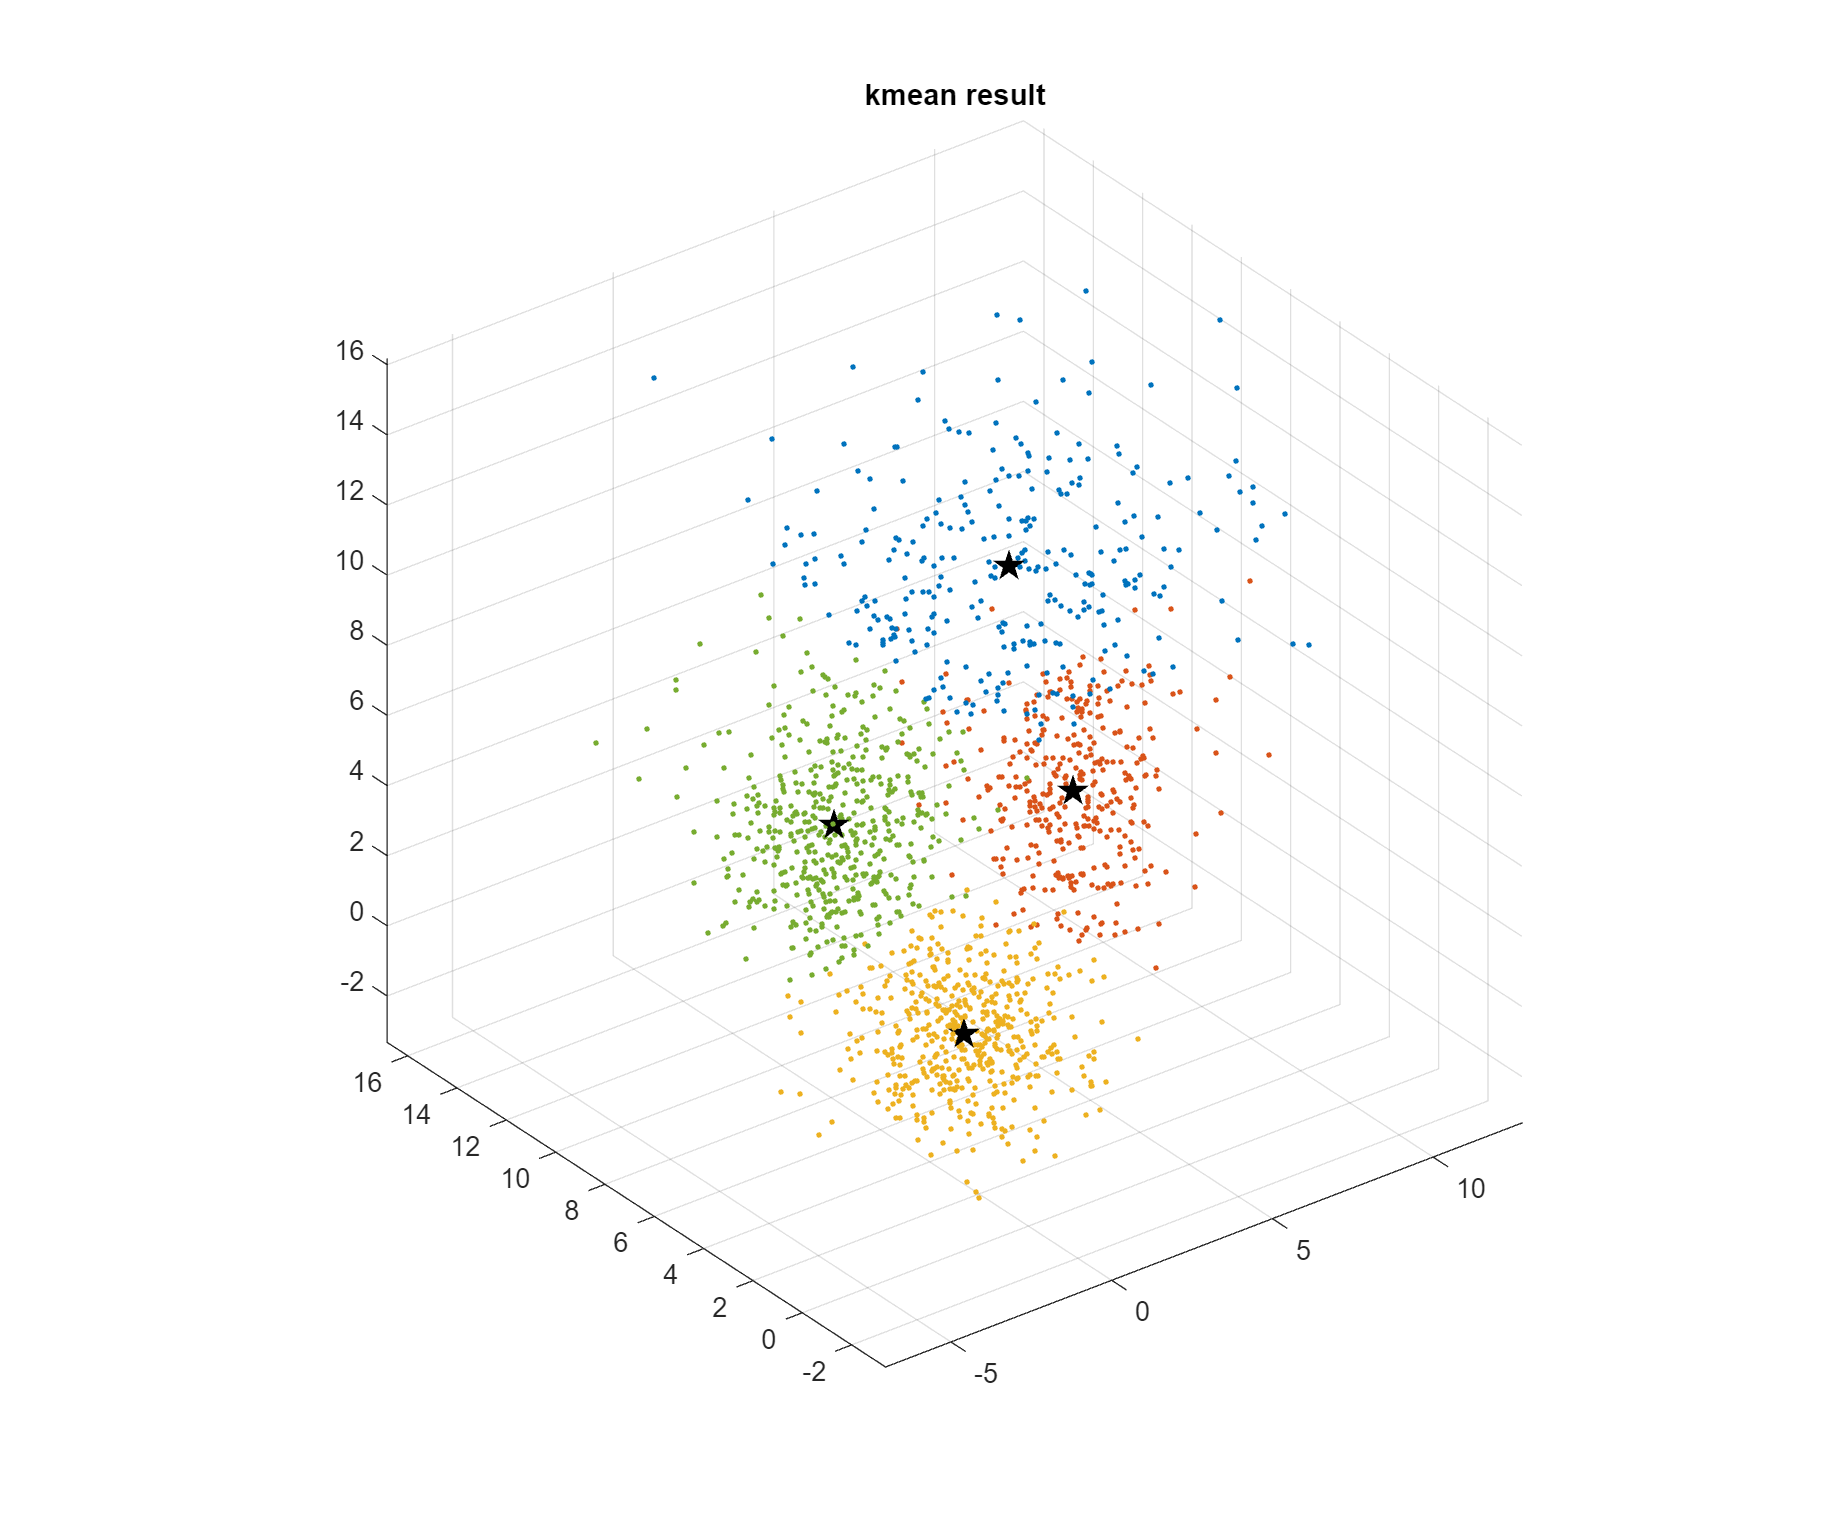

f = figure;

p1 = gobjects(n_set);
p2 = p1;
for i = 1:n_set
    p1(i) = plot3(C(1,i),C(2,i),C(3,i),'p',...
        'LineWidth',2,'Color',cl(i,:),'MarkerEdgeColor','k'); hold on
end

for i = 1:n_set
    data = O(:,idx==i);
    p2(i) = plot3(data(1,:),data(2,:),data(3,:),'.','Color',cl(i,:)); hold on
end
title('kmean result')
grid on; axis equal
set(f,'Units','normalized','Position',[0,0,0.6,0.8])

### Use k-mean Results as Initial Guess

s0 = NaN(3,3,n_set);
p_k0 = NaN(1,n_set);
for i = 1:n_set
    data = O(:,idx==i);
    data = data-C(:,i);
    p_k0(i) = size(data,2);
    s0(:,:,i) = data * data' / size(data,2);
end
m0 = C;
p_k0 = p_k0/sum(p_k0);

### Initial Guess 

% % m0 = [-1,4,-2;9,4,6;0,15,5;3,4,5]'; % good guess
% 
% p_k0 = [1,0.2,1,1]';
% m0 = [-1,4,-2;8,-8,10;0,15,5;3,4,5]'-1; % bad guess
% s0 = NaN(3,3,length(p_k0));
% s0(:,:,1) = eye(3);
% s0(:,:,2) = eye(3);
% s0(:,:,3) = eye(3);
% s0(:,:,4) = eye(3);
% 
% n_set = length(p_k0);

### EM Function

maxiter = 200; % max allowed iteration
tol = [1e-4,1e-4,1e-4]; % [m,s,p_k]
[m,s,p_k,m_all,s_all,pk_all] = emfit(O,m0,s0,p_k0,maxiter,tol);
count = size(pk_all,2)

count = 54

## Plot results

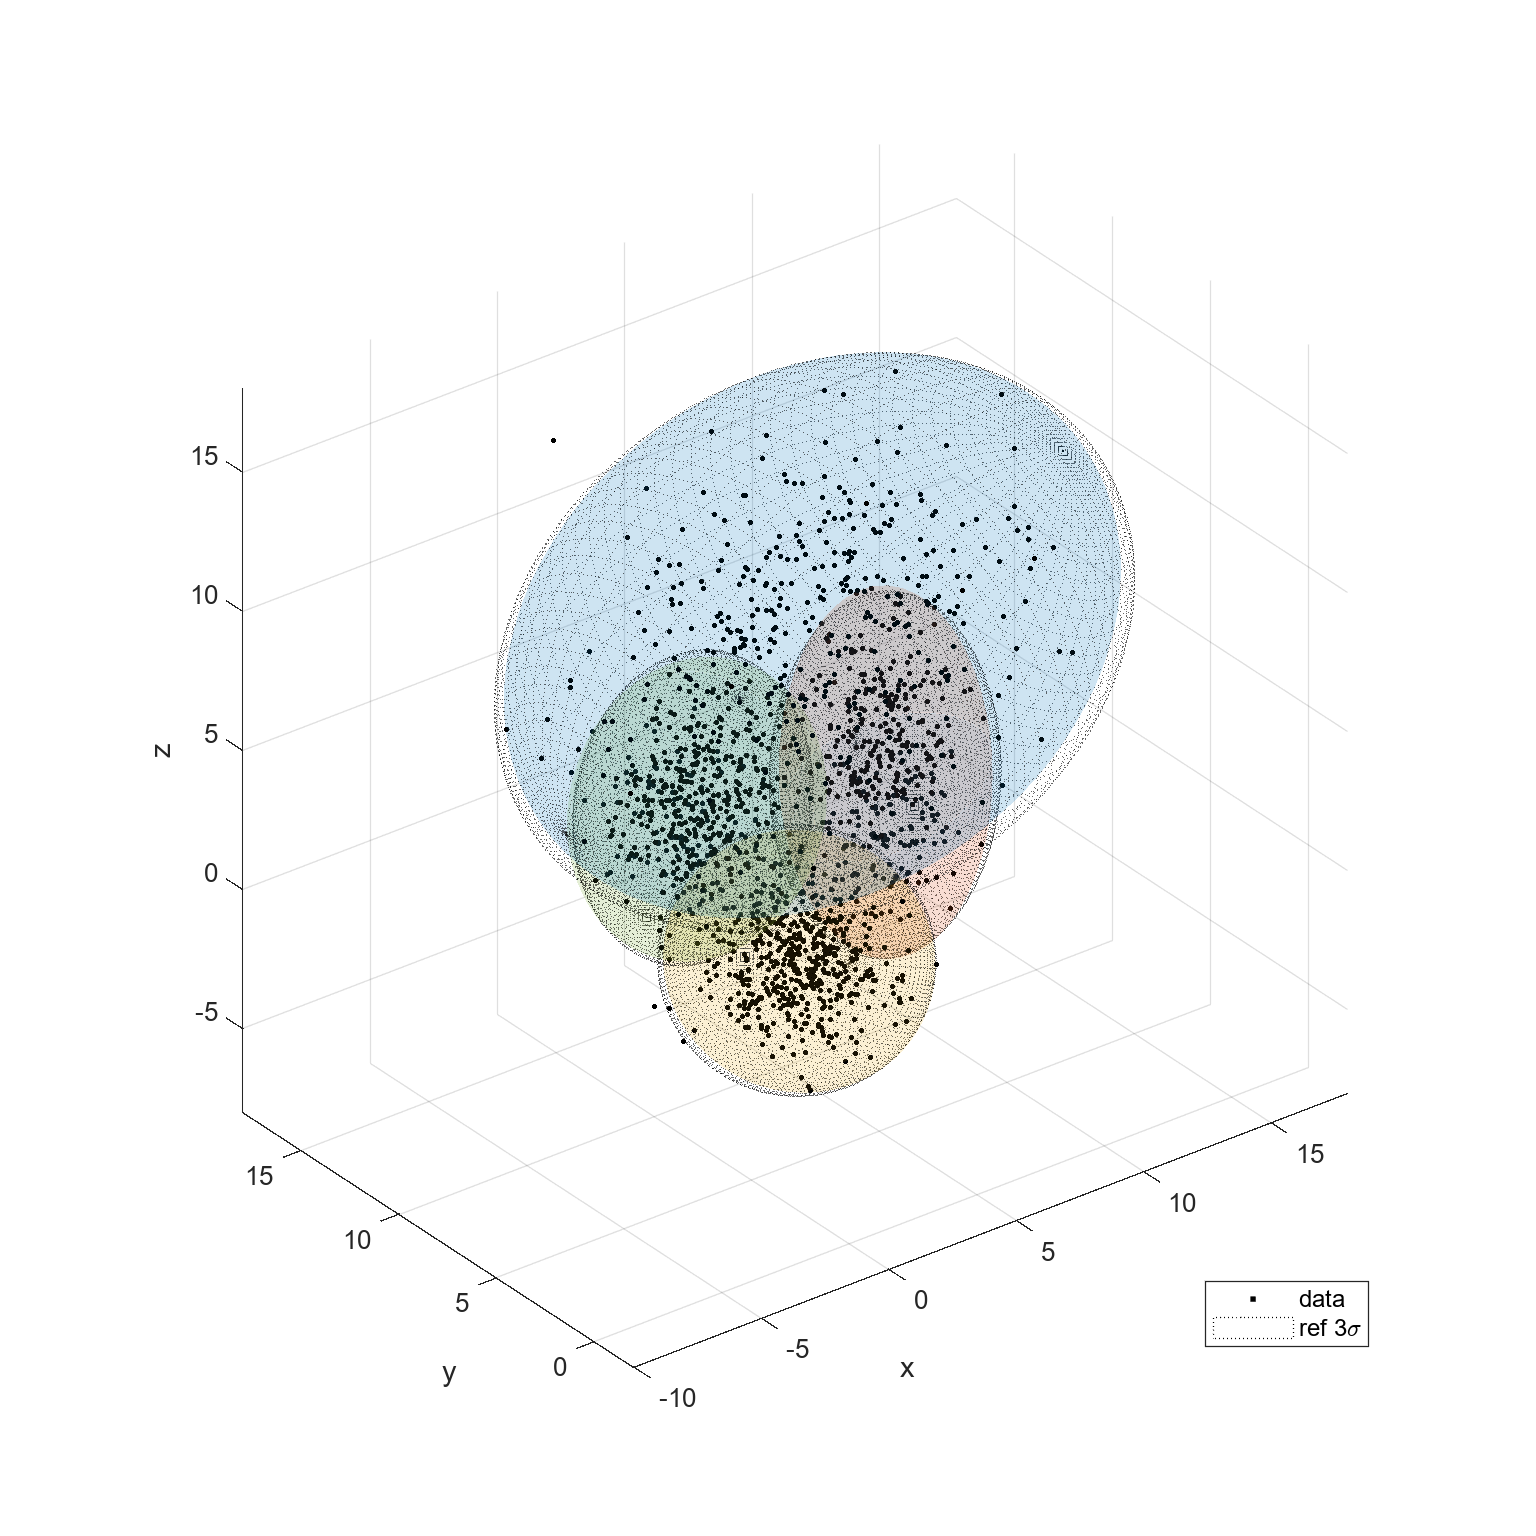

k = 3; % 3 sigma circle
n_pt = 50; % 50 pts on a ellip


f = figure;
po = plot3(O(1,:),O(2,:),O(3,:),'.k'); hold on
pp = gobjects(n_set,1); % initialize plots
pe = plot3(nan,nan,nan);

for i = 1:length(ellips_ref)
    surf(ellips_ref{i}(:,:,1),ellips_ref{i}(:,:,2),ellips_ref{i}(:,:,3),...
        'EdgeColor','k','FaceColor','none','EdgeAlpha',0.6,'LineStyle',':'); hold on    
end

for i = 1:n_set

    ellip = cov2ellip(s_all(:,:,i,1),k,m_all(:,1,i),n_pt); % 3 sigma ellip
    pp(i) = surf(ellip(:,:,1),ellip(:,:,2),ellip(:,:,3),...
        'EdgeColor','none','FaceColor',cl(i,:),'FaceAlpha',0.1); hold on
end
pr = surf(nan(2,2),nan(2,2),nan(2,2),'EdgeColor','k','FaceColor','none','LineStyle',':');
grid on; axis equal
legend([po,pr],{'data','ref 3\sigma'},'Location','southeast')
xlabel('x'); ylabel('y'); zlabel('z')
xlim([-10,18]); ylim([-2,18]); zlim([-8,18])
set(f,'Units','normalized','Position',[0.25,0.08,0.5,0.8])

for ii = 1:count
    for i = 1:n_set
        if any(isnan(m_all(:,ii,i)))
            pp(i).XData = NaN(2,2);
            pp(i).YData = NaN(2,2);
            pp(i).ZData = NaN(2,2);            
        else
            ellip = cov2ellip(s_all(:,:,i,ii),k,m_all(:,ii,i),n_pt);
            pp(i).XData = ellip(:,:,1);
            pp(i).YData = ellip(:,:,2);
            pp(i).ZData = ellip(:,:,3);
        end
    end
    if ii == 1
        for j = 1:20
            pe.XData = nan;
            drawnow
        end
    end
    drawnow
end